依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

迁移模板时序特征

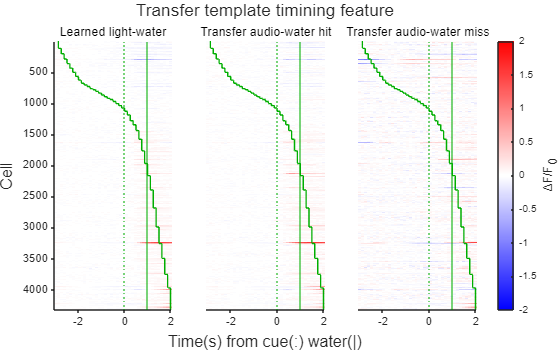

Impl('光声迁移命中错失',["Learned light-water","Transfer audio-water hit","Transfer audio-water miss"]);

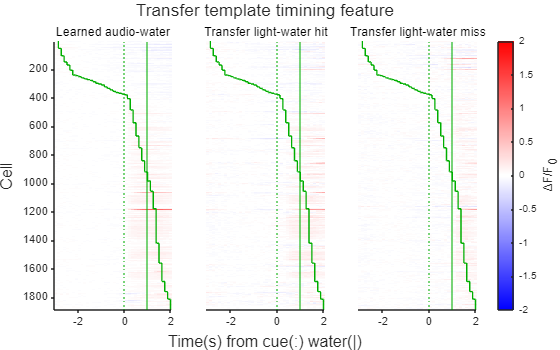

Impl('声光迁移命中错失',["Learned audio-water","Transfer light-water hit","Transfer light-water miss"]);

function Impl(SheetName,SubTitles)
import TransferLearning.*
Data=NtatsFromSheetname(SheetName,Flags.Different_cells_stripped).NTATS{:,:,["Learned","Transfer_hit","Transfer_miss"]};
[~,PeakTime]=max(Data(:,:,1),[],2);
[PeakTime,SortIndex]=sort(PeakTime/8-3);
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
[Layout,Axes]=BasicHeatmap(Data(SortIndex,:,:),SubTitles,Colors,false,CLim=[-2,2]);
Ys=1:height(Data);
for A=1:numel(Axes)
	line(Axes(A),PeakTime,Ys,Color=Colors(3,:));
end
title(Layout,'Transfer template timining feature');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath(sprintf('%s.达峰时序热图.svg',SheetName)),'-dsvg');
end